# Signal Detrending

- when you want to focus on local changes in the signal which is trending globally

### Linear Detrending

- generate a signal

- detrend it

- plot the signals

n = 2000; % number of signal points
signal = cumsum(randn(1,n)) + linspace(-30,30,n);
detrended = detrend(signal);
sig_mean = round(mean(signal), 2);
det_mean = round(mean(detrended), 2);

### Plot the signals

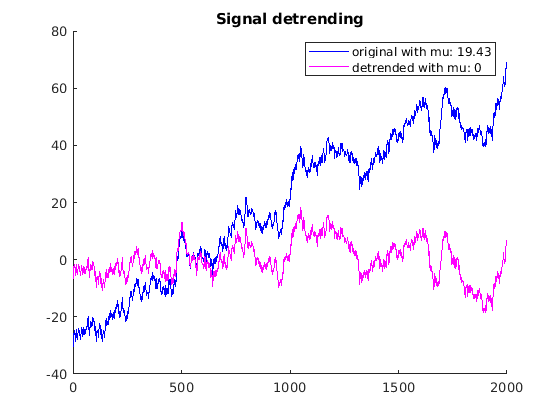

figure(1);
hold on;
sig_plot = plot(signal, 'b');
det_plot = plot(detrended, 'm');
legend([sig_plot, det_plot], ["original with mu: " + num2str(sig_mean), "detrended with mu: " + num2str(det_mean)]);
title("Signal detrending");
hold off;